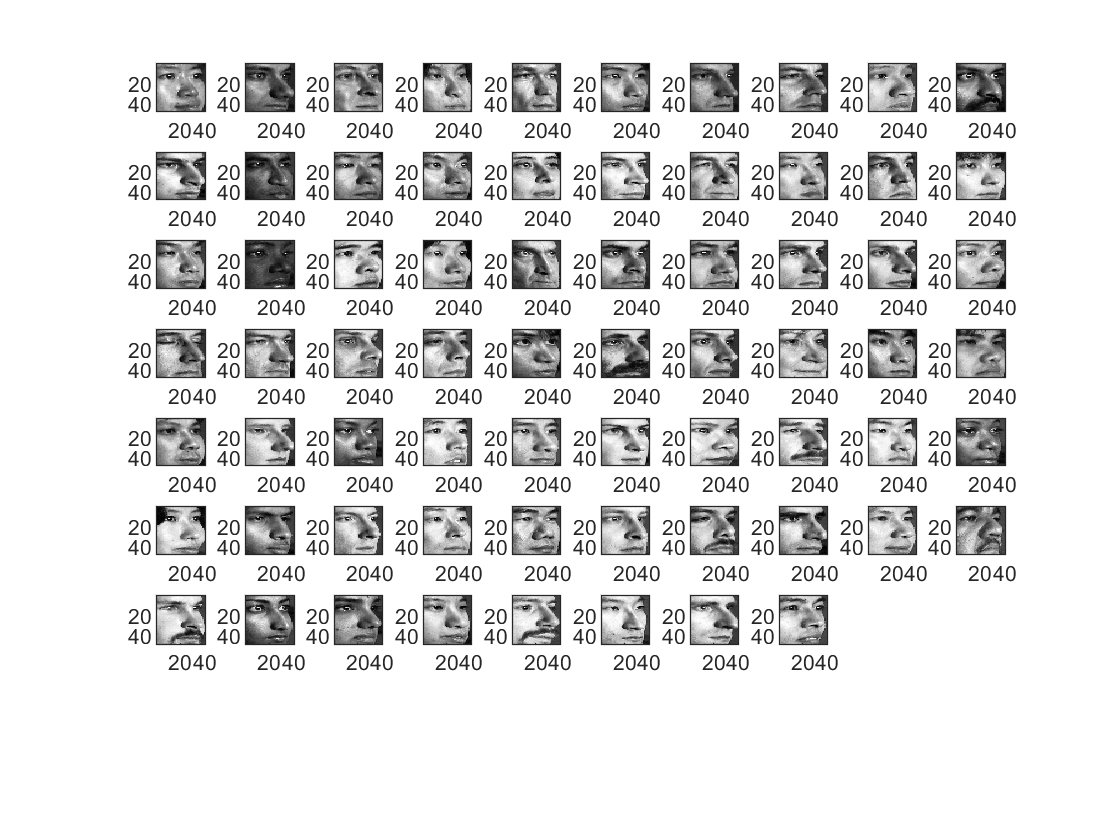

data = load('pose.mat');
pose = data.pose;
% Each image is 48x40 pixel image, there are 13 images for each subject and 68 subjects
figure, clf;
colormap 'gray';
%display the 1st image of each subject
for i=1:68
    subplot(8,10,i);
    imagesc(pose(:,:,1,i)); 
end

## Multiple Discriminant Analysis

trn_sz = 10;
[d1, d2] = deal(size(pose,1), size(pose,2));
X=zeros(trn_sz*size(pose,4), d1*d2);
Y_trn=[];
for i=1:size(pose,4)
    for j=1:trn_sz
        tmp = pose(:,:,j,i);
        X((i-1)*trn_sz + j,:) = tmp(:)';
    end
    Y_trn = [Y_trn; ones(trn_sz,1)*i];
end
Y_lbl=[]
for i=1:size(pose,4)
    for j=trn_sz+1:size(pose,3)
        tmp = pose(:,:,j,i);
        X_tst((i-1)*(size(pose,3) - trn_sz) + j - trn_sz,:) = tmp(:)';
        Y_lbl = [Y_lbl;i];
    end
end
%Start MDA analysis
mu_tot = mean(X,"all");
mu_i = zeros(size(pose,4),d1*d2);
Sb = zeros(d1*d2); 
Sw = zeros(d1*d2);
for i=1:size(pose,4)
    mu_i(i,:) = mean(X((i-1)*trn_sz+1:(i-1)*trn_sz+10,:));
    Sb = Sb + trn_sz*(mu_i(i) - ones(1,d1*d2)*mu_tot)*(mu_i(i) - ones(1,d1*d2)*mu_tot)';
    Sw = Sw + (X((i-1)*trn_sz+1:(i-1)*trn_sz+10,:) - ones(trn_sz,1)*mu_i(i,:))'*(X((i-1)*trn_sz+1:(i-1)*trn_sz+10,:) - ones(trn_sz,1)*mu_i(i,:));
end

[eig_vec , eig_val] = eig(Sb,Sw);
[eig_s, isort] = sort(diag(eig_val),"descend");
eig_vec = eig_vec(:,isort);
W = eig_vec(:,1:size(pose,4)-1);

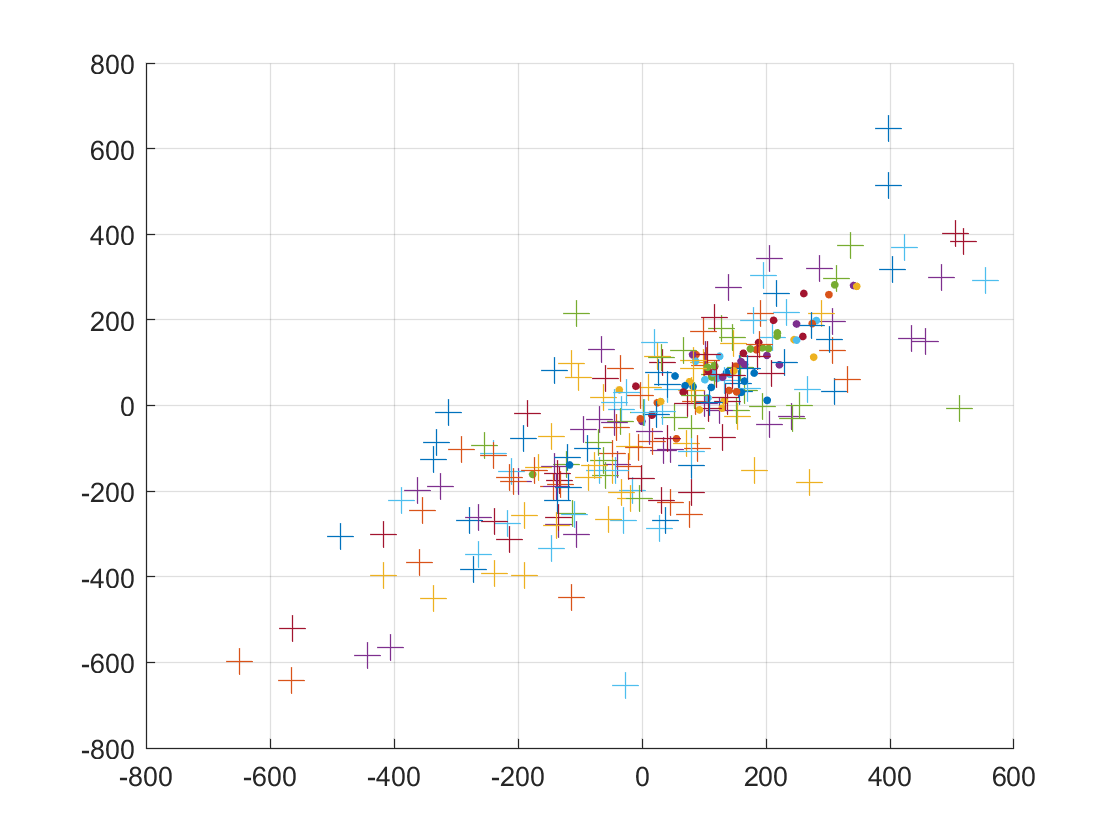


Y = X*W;
Y_tst = X_tst*W;
figure, clf; grid; hold on;
for i=1:1
    plot3(Y(i*10-9:i*10,1),Y(i*10-9:i*10,2),Y(i*10-9:i*10,3),'.','MarkerSize',10);
    plot3(Y_tst(i*3-2:i*3,1),Y_tst(i*3-2:i*3,2),Y_tst(i*3-2:i*3,3),'+','MarkerSize',10);
end
hold off

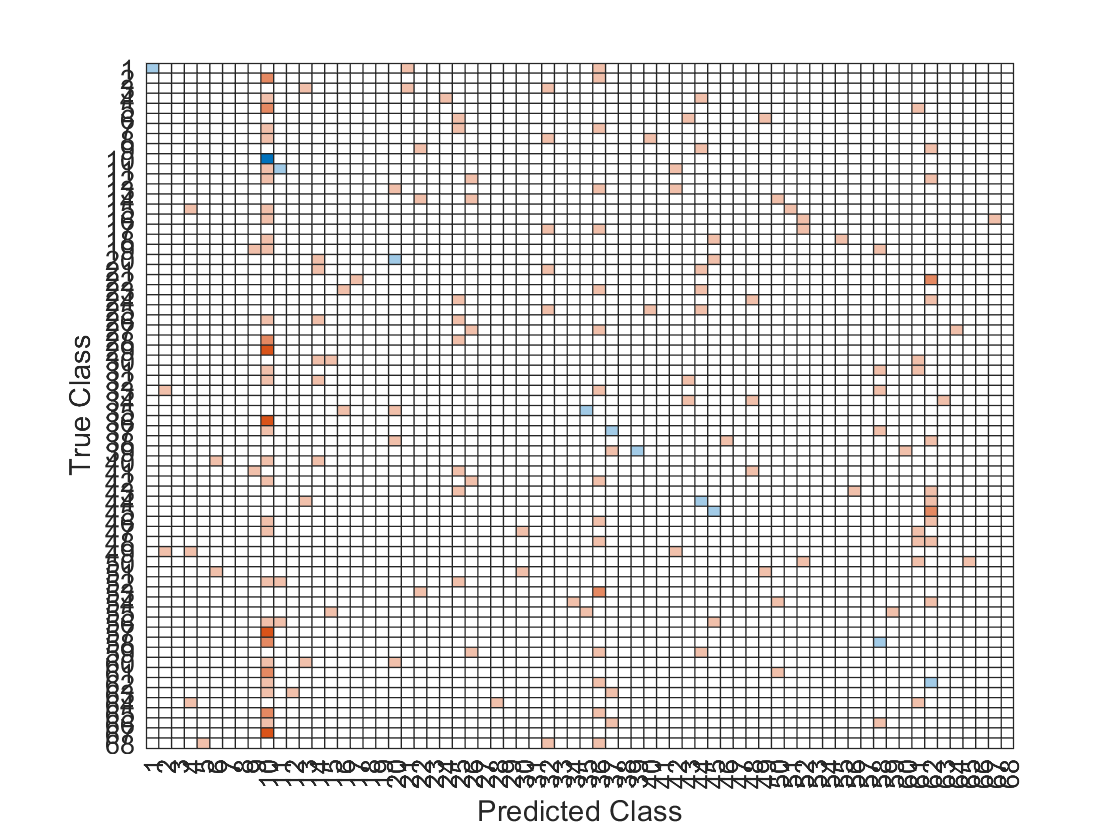

k_face = fitcknn(Y,Y_trn,"NumNeighbors",5,"Distance","euclidean");
label = predict(k_face,Y_tst);

C = confusionmat(Y_lbl,label);
cm = confusionchart(C);